# Replace Content Placeholder with Content

Add four `Title and Content` slides to a presentation. Replace the content placeholder of the first slide with text, the second slide with a table, the third slide with a picture, and the fourth slide with a multilevel list.

Import the PPT package so that you do not have to use long, fully qualified names for the PPT API classes.

import mlreportgen.ppt.*

Create a presentation.

ppt = Presentation("myContentPlaceholderPresentation.pptx");
open(ppt);

Add a slide with a `Title and Content` layout.

slide1 = add(ppt,"Title and Content");

Use the `find` method of the slide object to find the placeholder object that has the name `Title`.

titlePlaceholderObj1 = find(slide1,"Title");

The `find` method returns an `mlreportgen.ppt.TextBoxPlaceholder` object.

Replace the placeholder content with the title text.

replace(titlePlaceholderObj1,"Content Replaced with Paragraph");

Use the `find` method of the slide object to find the placeholder object that has the name `Content`.

contentPlaceholderObj1 = find(slide1,"Content");

The `find` method returns an `mlreportgen.ppt.ContentPlaceholder` object.

Replace the placeholder content with a paragraph.

replace(contentPlaceholderObj1,Paragraph("This is my paragaph"));

Add a second slide with a `Title and Content` layout.

slide2 = add(ppt,"Title and Content");

Replace the placeholder for the title with the title text.

titlePlaceholderObj2 = find(slide2,"Title");
replace(titlePlaceholderObj2,"Content Replaced with Table for Order 2 Magic Square");

Replace the content placeholder with a table.

contentPlaceholderObj2 = find(slide2,"Content");
replace(contentPlaceholderObj2,Table(magic(2)));

Add a third slide with a `Title and Content` layout.

slide3 = add(ppt,"Title and Content");

Replace the placeholder for the title with the title text.

titlePlaceholderObj3 = find(slide3,"Title");
replace(titlePlaceholderObj3,"Content Replaced with Picture of Peppers");

Replace the content placeholder with a picture.

contentPlaceholderObj3 = find(slide3,"Content");
replace(contentPlaceholderObj3,Picture("peppers.png"));

Add a fourth slide with a `Title and Content` layout.

slide4 = add(ppt,"Title and Content");

Replace the placeholder for the title with the title text.

titlePlaceholderObj4 = find(slide4,"Title");
replace(titlePlaceholderObj4,"Content Replaced with a Multilevel List");

Create content for a multilevel list. You can represent a multilevel list as a cell array that contains one or more cell arrays that represent sublists. Use an `mlreportgen.ppt.Paragraph` object to format an item in the list.

greenTea = Paragraph("Green Tea");
greenTea.FontColor = "green";

multilevelContent = { ...
    "Coffee", ...
    "Tea", ...
    { ...
        "Black Tea", ...
        greenTea, ...
    }, ...
    "Milk", ...
    };


Replace the `Content` placeholder with the multilevel list content.

contentPlaceholderObj4 = find(slide4,"Content");
replace(contentPlaceholderObj4,multilevelContent);

Close and view the presentation.

close(ppt);
rptview(ppt);

Here are the generated slides:

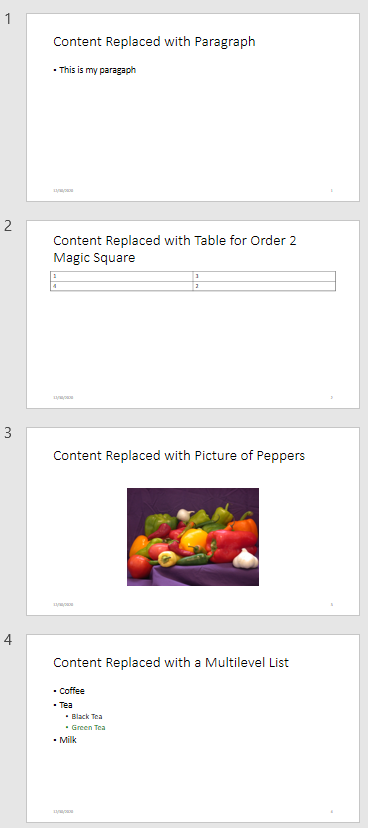

*Copyright 2020 The MathWorks, Inc.*